## Case Study: Self-Organizing Sequential Search Rules

### Warren D. Craft

#### Based on class discussion and examples

#### in CS 533: Experimental Methods in CS

#### (Spring 2019, University of New Mexico, taught by A. Mueen and G. M. Fricke)

First, some slides from the related lecture (Spring 2019), …

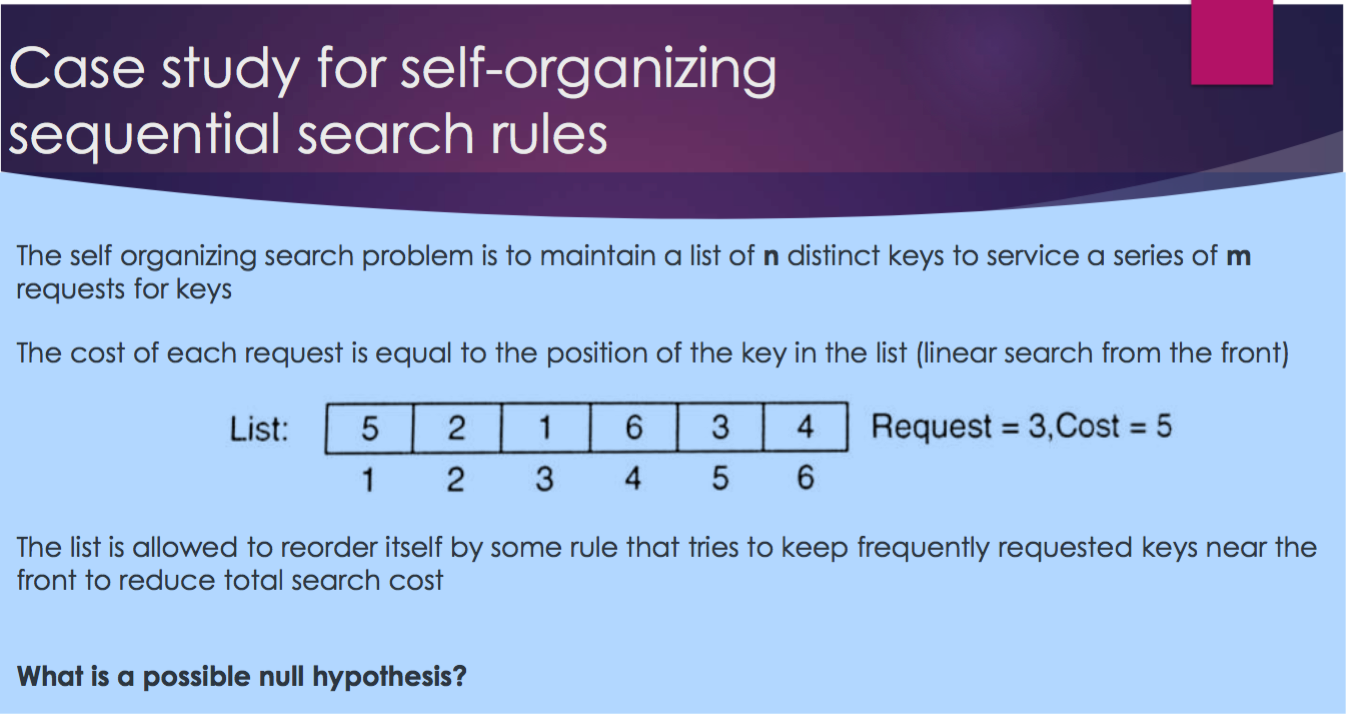  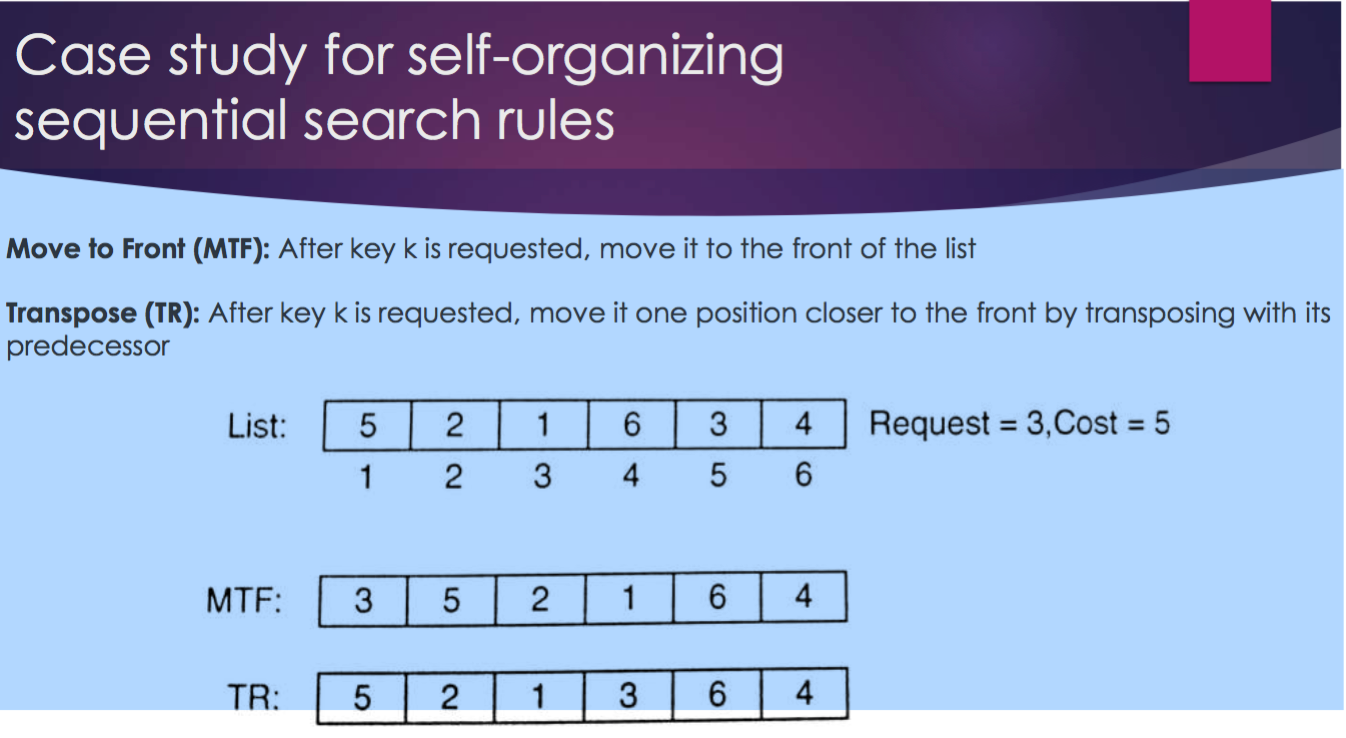

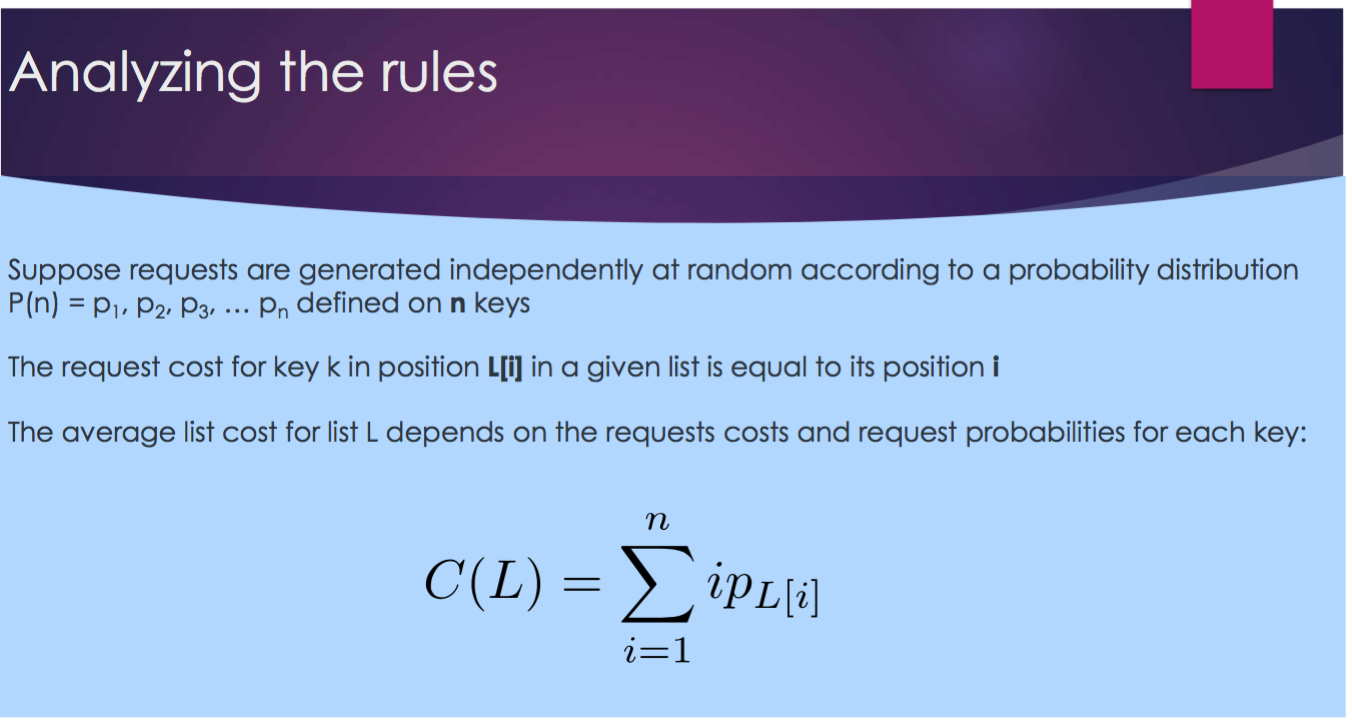 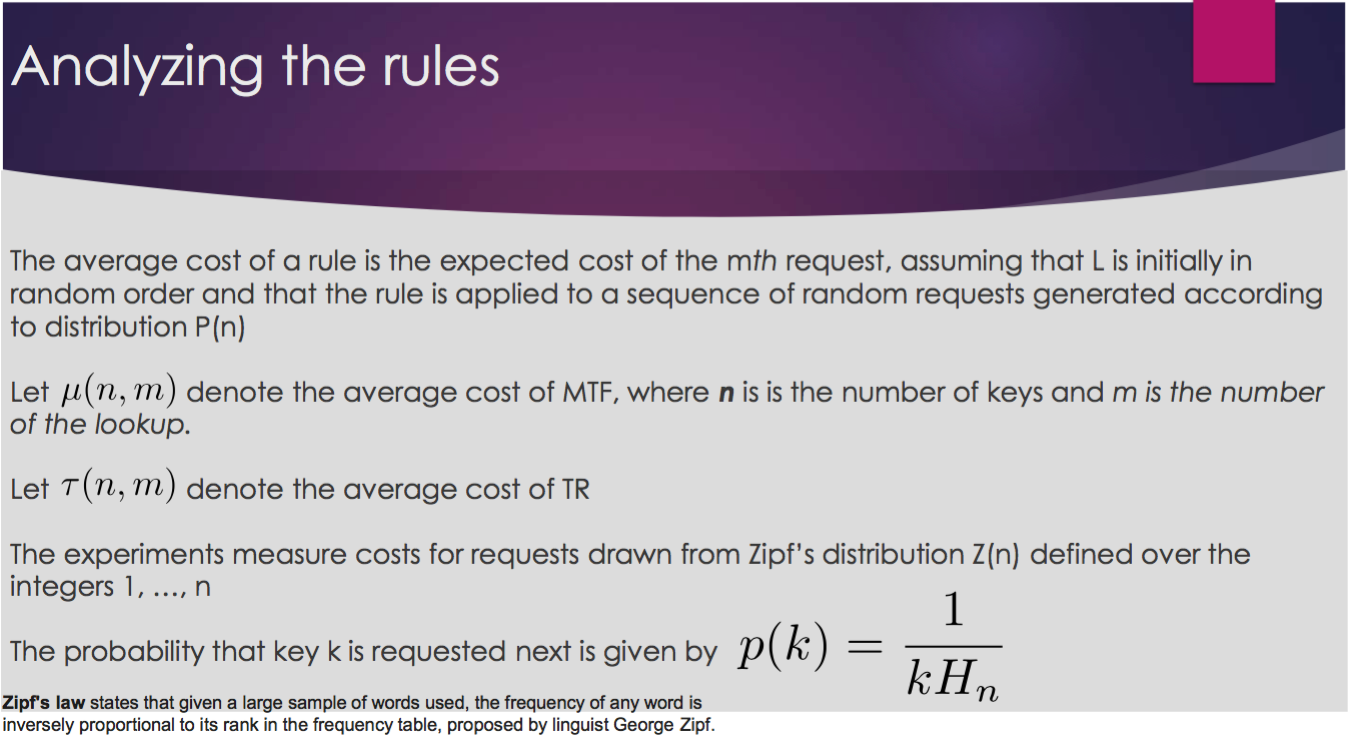

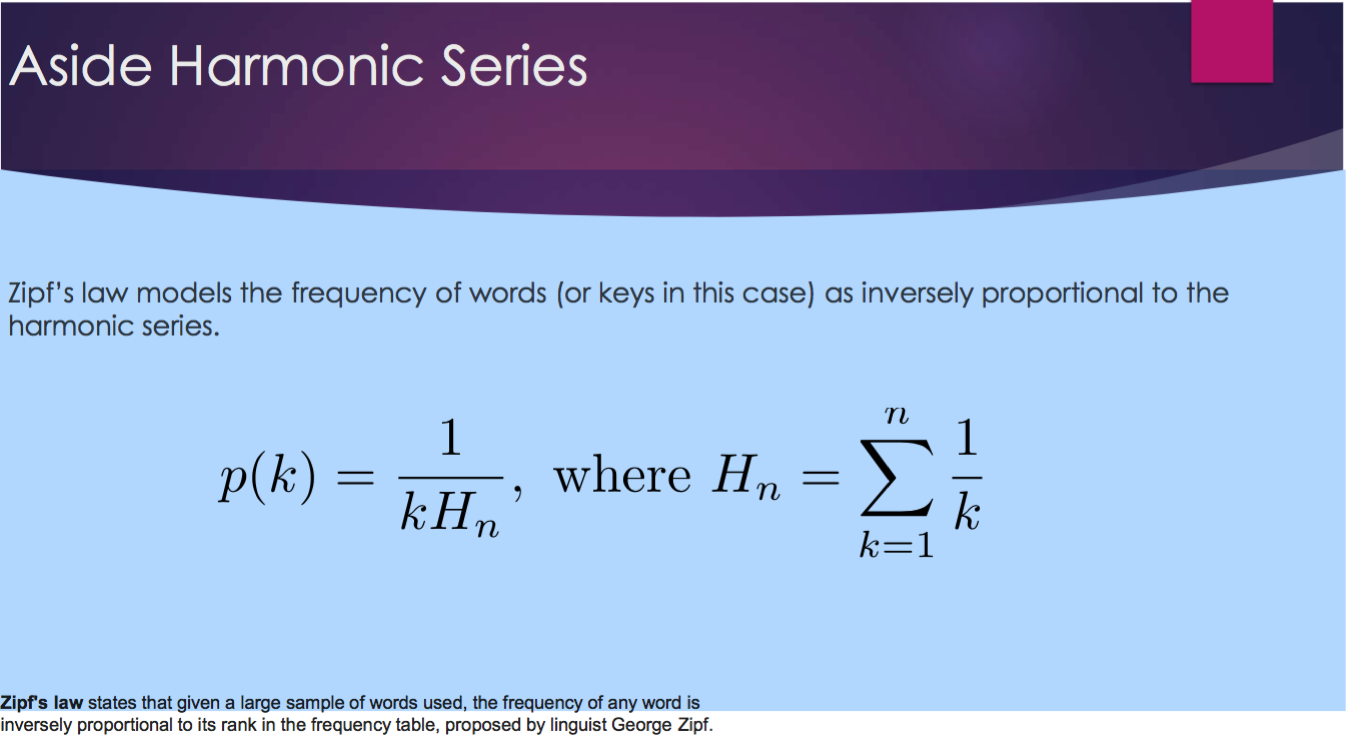 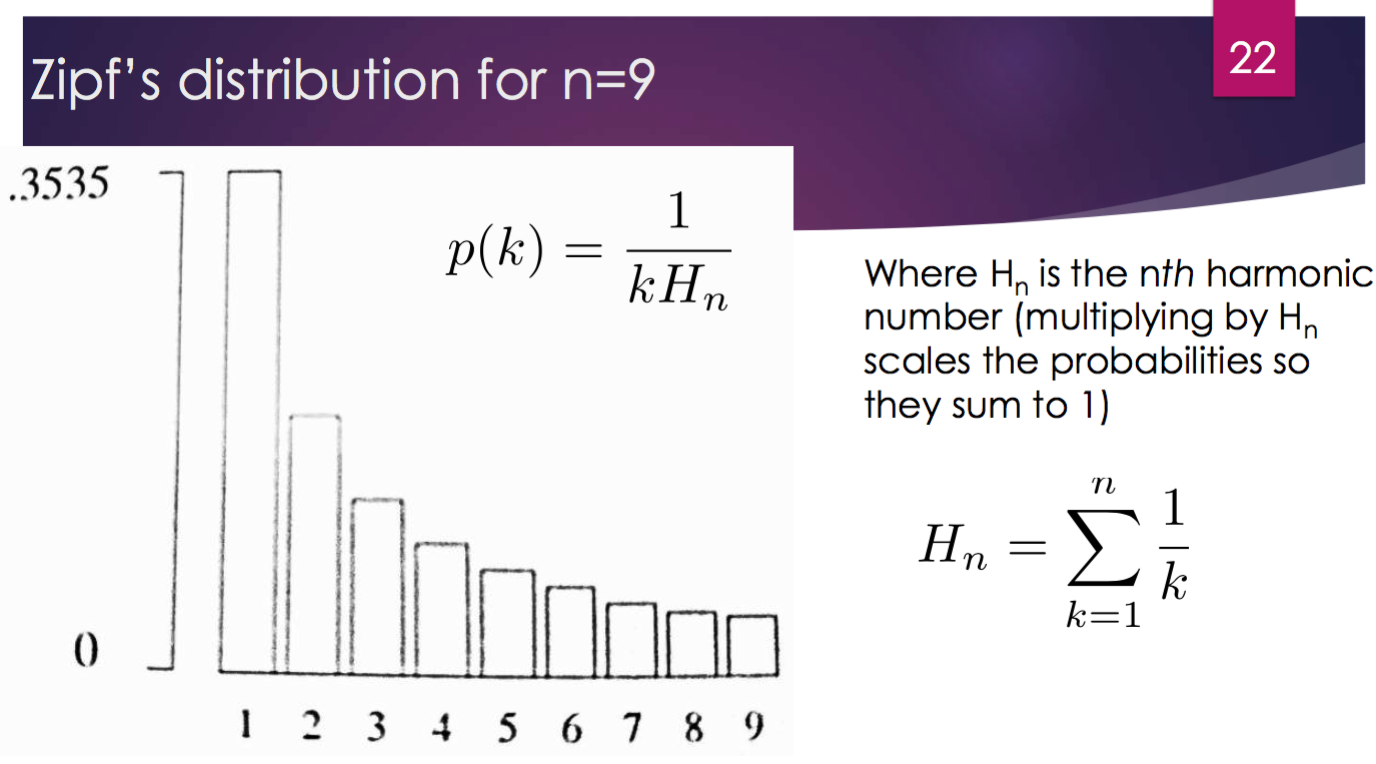 

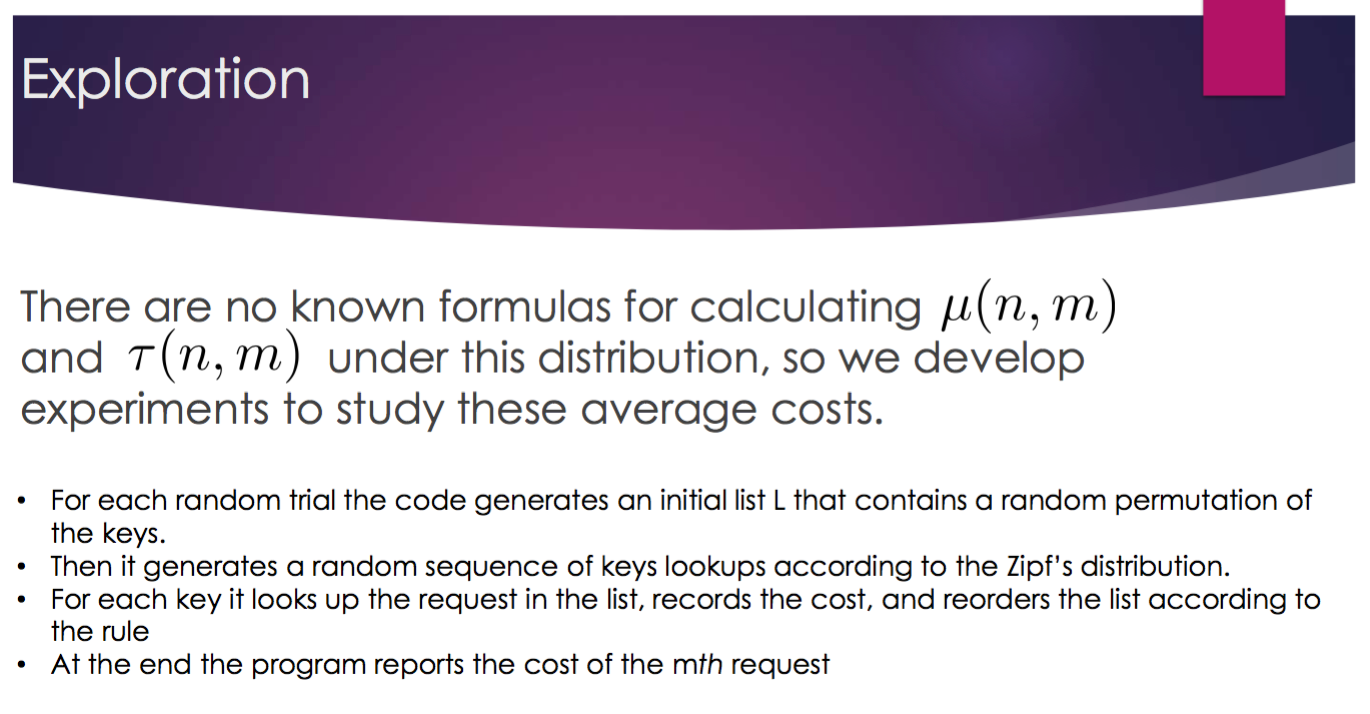 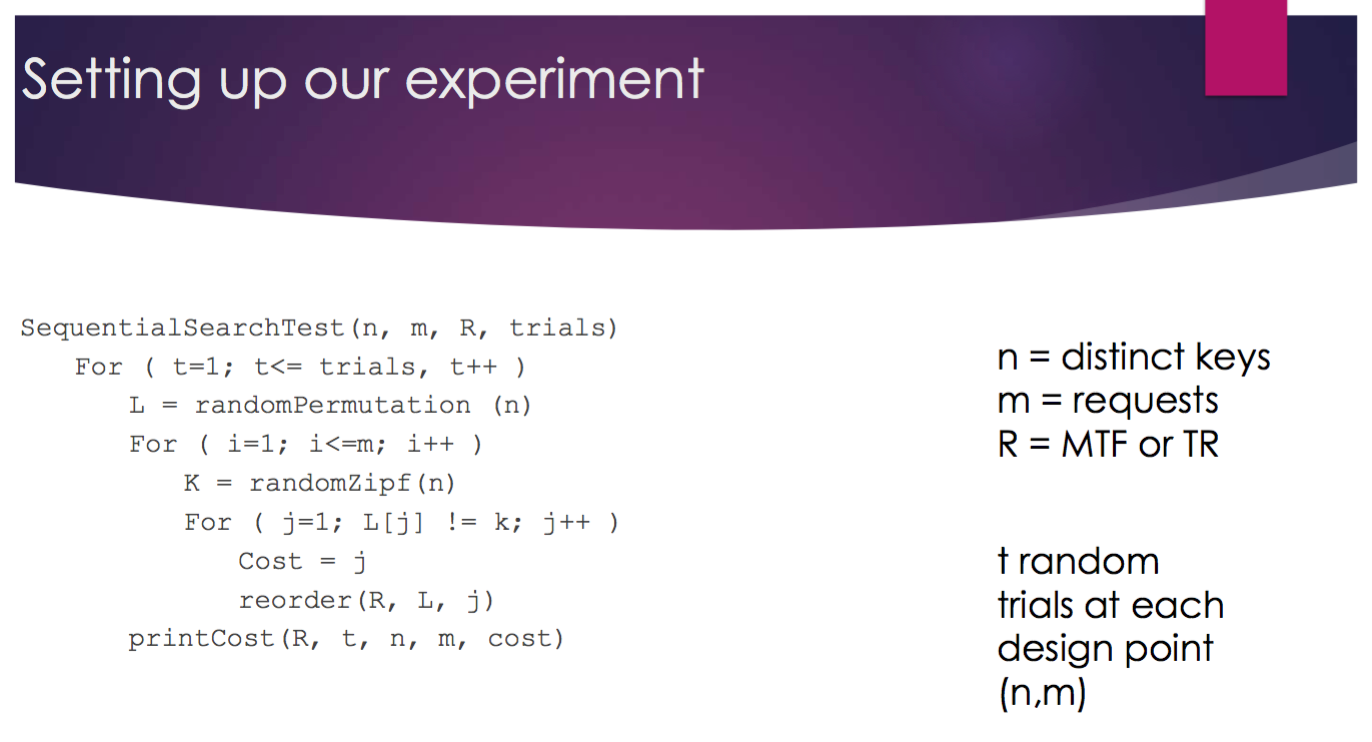  

## The Zipf Distribution

We begin by establishing a method for sampling from a Zipfian distribution. This is not a critical piece of this case study but provides one possible model for the distribution of requests arriving for key searches in the list of keys.

The definition of the zipf(*j*, *n*) probability density function (pdf) appears at the end of this mlx file, and in the code shown immediately below this text we illustrate the resulting pdf for a specific numberOfKeys. Along the way, we verify that for any specific number of keys, the sum of the resulting collection of probabilities is 1, as required in any well-behaved pdf. In the *next* section below we actually implement the random-sampling process.

% set a convenient format for printing values
format shortG

% set the number of "keys" considered in each list of keys
% the so-called keys will be integers 1-numberOfKeys
numberOfKeys = 10;

% allocate space for storing the relative probabilities of the keys
zipfValues = zeros(numberOfKeys, 1);

% establish the probability for each key value,
% using the zipf() function defined in the functions section
% at the bottom of this mlx file
for i = 1:1:numberOfKeys
    zipfValues(i) = zipf(i, numberOfKeys);
end

% check our calculations: the sum of the calculated zipf values
% should be (approximately) 1
sum(zipfValues)

ans =             1


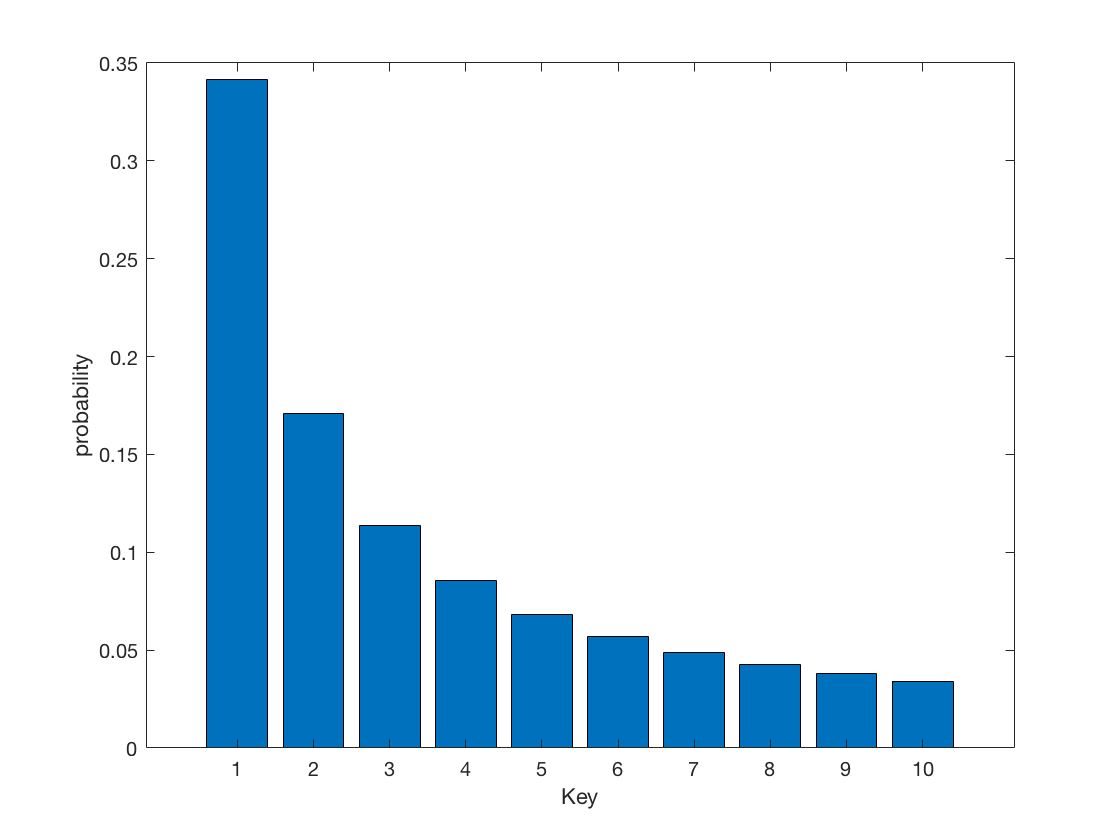

% look at the resulting probability density function (pdf)
bar(zipfValues)
xlabel('Key')
ylabel('probability')

## Sampling from a Zipf Distribution

In this section we generate pseudo-random integers sampled from a Zipf distribution of integers, using a rejection method (as discussed in Kalos & Whitlock (2008), Section 3.5, pp 53–61).

Notice that the pdf has a maximum value that depends on the number of keys *n*. When *n* = 10, for example, the max probability (associated with the key 1) is:

double(zipf(1, 10))

ans =       0.34142


We effect a sampling of the Zipf distribution by first picking an integer x randomly from 1 to numberOfKeys, then a second random number y = maxProb * rand(0,1). If y ≤ zipfValues(x), we keep x as one of our randomly-generated values, else we discard it and repeat the process.

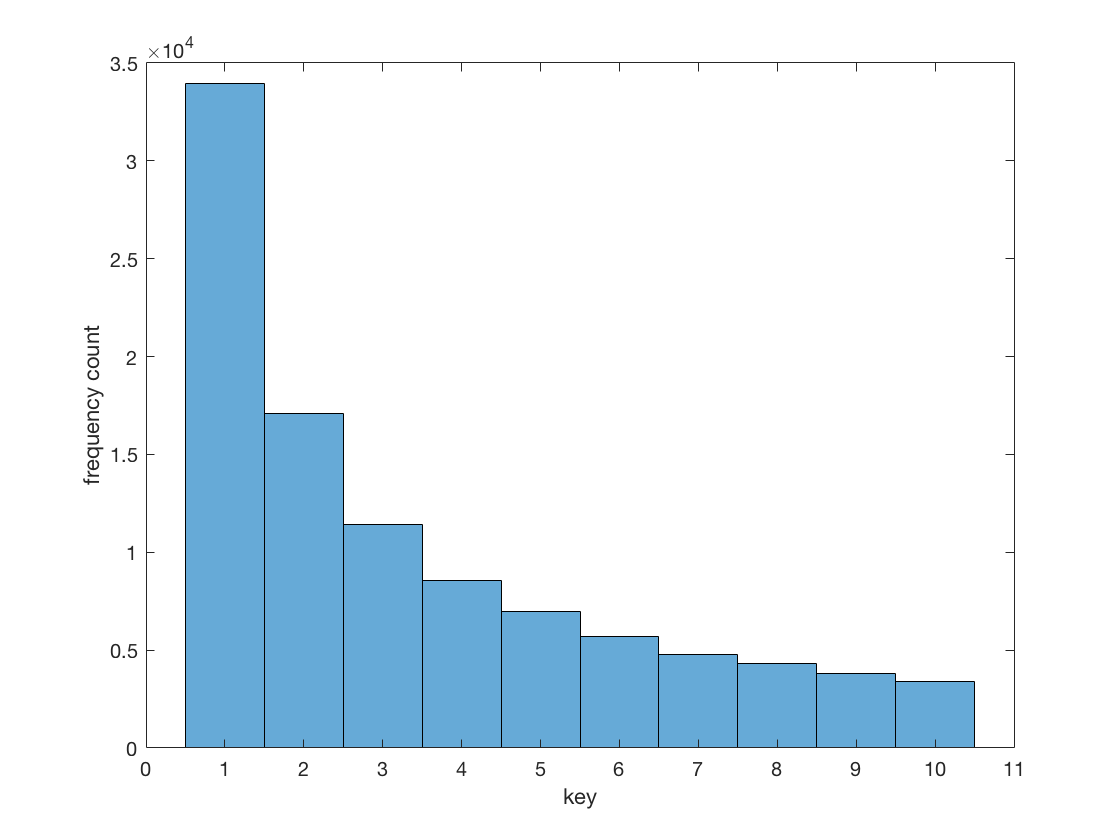

% establish the maximum of the pdf function for our context
maxProb = double(zipf(1, numberOfKeys));

% set the desired sample size
desiredNumberOfValues = 100000;

% set the number of values in sample so far:
actualNumberOfValues = 0;

% allocate space for the eventual sample:
sampleOfValues = zeros(desiredNumberOfValues, 1);

% perform the rejection-based sampling
while actualNumberOfValues < desiredNumberOfValues
    % pick a random key
    rand01 = randi(numberOfKeys);
    % pick a random real from (0, maxProb)
    rand02 = maxProb * rand();
    % determine if initial rand01 should be kept or rejected
    if rand02 <= zipfValues(rand01)
        actualNumberOfValues = actualNumberOfValues + 1;
        sampleOfValues(actualNumberOfValues) = rand01;
    end
end

% take a look at the (frequency) distribution created
histogram(sampleOfValues)
xlabel('key')
ylabel('frequency count')

% express the distribution in terms of probabilities:
sampleOfValuesProbabilities = zeros(numberOfKeys, 1);
for i = 1:numberOfKeys
    sampleOfValuesProbabilities(i) = sum(sampleOfValues(:)==i);
end
sampleOfValuesProbabilities = ...
    sampleOfValuesProbabilities/sum(sampleOfValuesProbabilities)

sampleOfValuesProbabilities =        0.3396
      0.17114
      0.11425
       0.0856
      0.06965
      0.05701
       0.0476
      0.04308
      0.03799
      0.03408


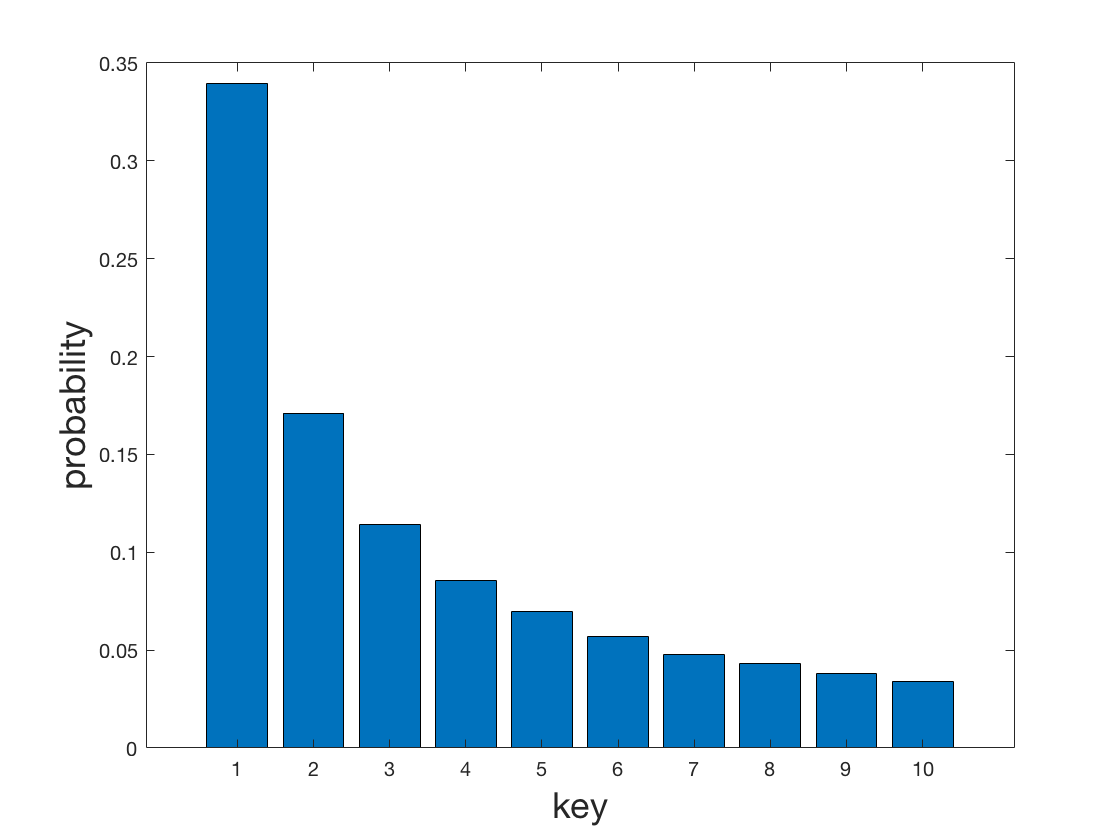

% take a look at the probability distribution created
bar(sampleOfValuesProbabilities)
xlabel('key', 'FontSize', 18)
ylabel('probability', 'FontSize', 18)

And we can take a quick look at the difference between the empirically-generated probabilities and the theoretical ones, standardized over the theoretical probabilities. The for large samples (say ≥ 100,000), the differences tend to have a max absolute value less than about 5% over time, and generally much smaller differences:

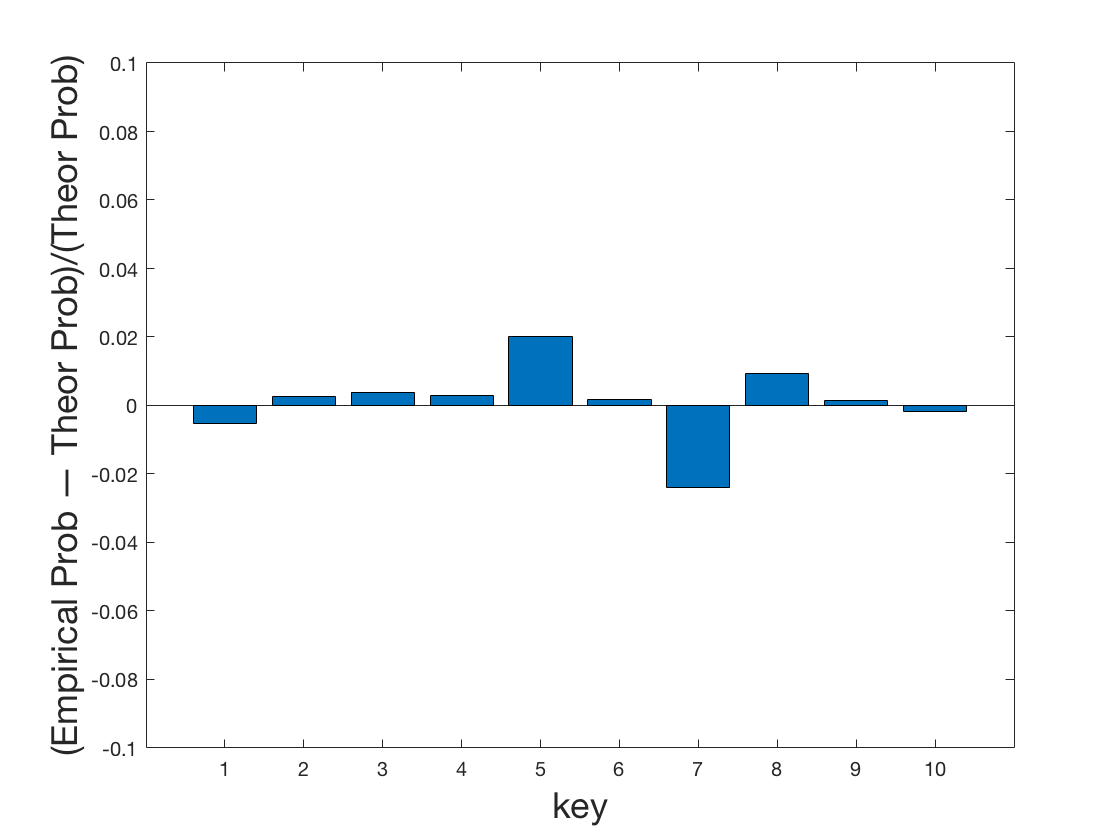

% look at the difference between the empirical distribution values
% and the theoretical Zipf distribution values, std'ized by the theoretical values:
xs = 1:1:10;
stdDeltas = (sampleOfValuesProbabilities-zipfValues)./zipfValues;
bar(xs, stdDeltas);
xlabel('key', 'FontSize', 18)
ylabel('(Empirical Prob — Theor Prob)/(Theor Prob)', 'FontSize', 18)
axis([0 11 -0.1 0.1])

## The zipf(*j*, *n*) function

The zipf(j, n) function below returns the Zipfian distribution-based probability of the jth-ranked item of a collection of *n* possible items:

function p = zipf(j, n)
% Returns p(j) = 1/(j H_n), where H_n = sum(1/k) for k = 1 to n,
% a standardized pdf version of Zipf's Law.
% Zipf's Law states that "given some corpus of natural language utterances,
% the frequency of any word is inversely proportional to its rank in the
% frequency table" [https://en.wikipedia.org/wiki/Zipf%27s_law.
syms k;
p = 1/(j * symsum(1/k, k, [1 n]));
end